close all
clear
clc

生成低通滤波器系数

[b, a] = butter(5, 0.3);

绘制系统群延时

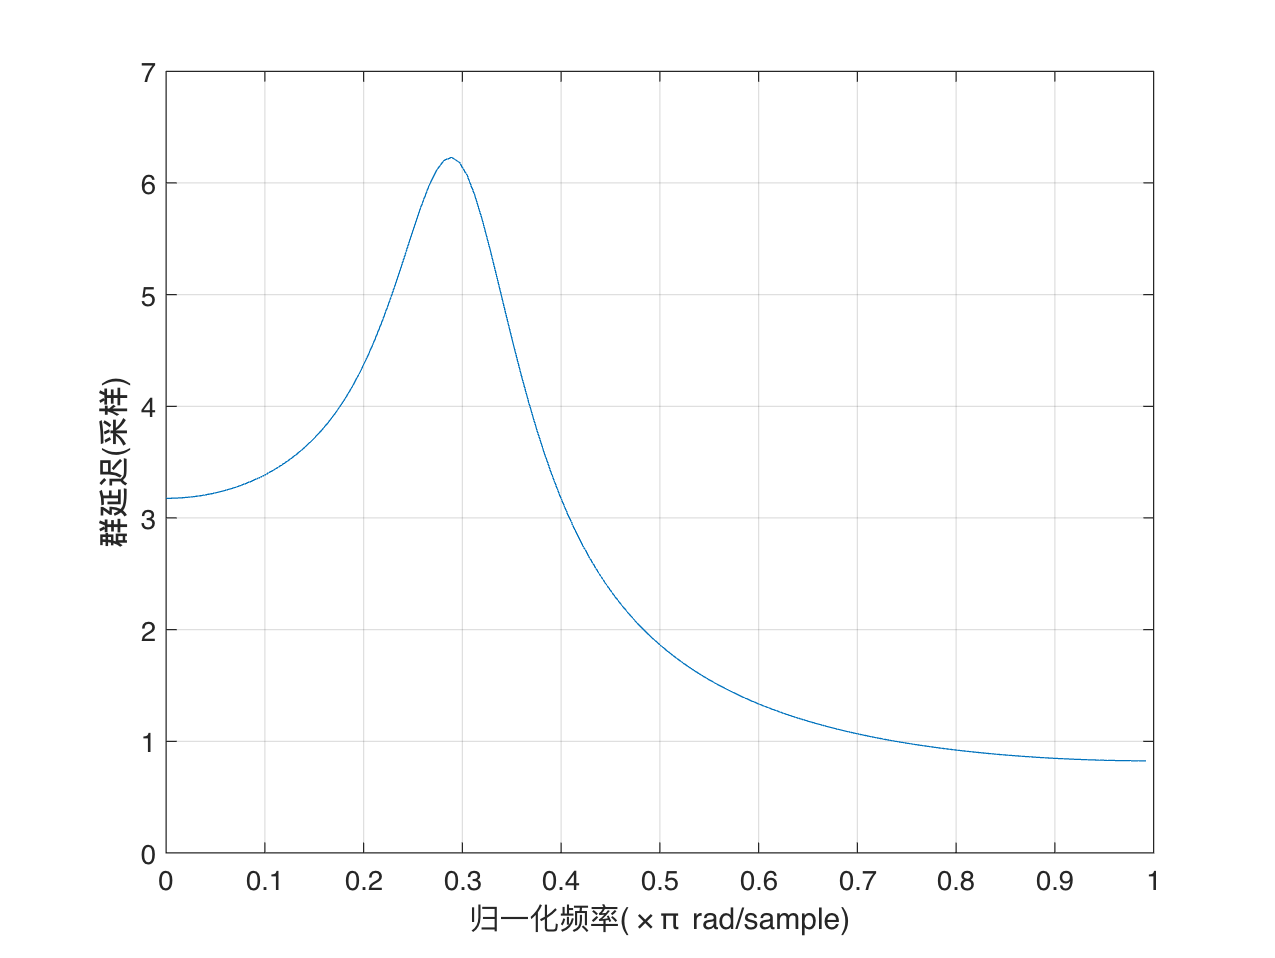

grpdelay(b, a, 128);

定义采样时刻和单频信号，激励系统得到响应

n = 0:30;
x = sin(0.2*pi*n);
y = filter(b,a,x);

绘制激励和响应波形，观测群延时

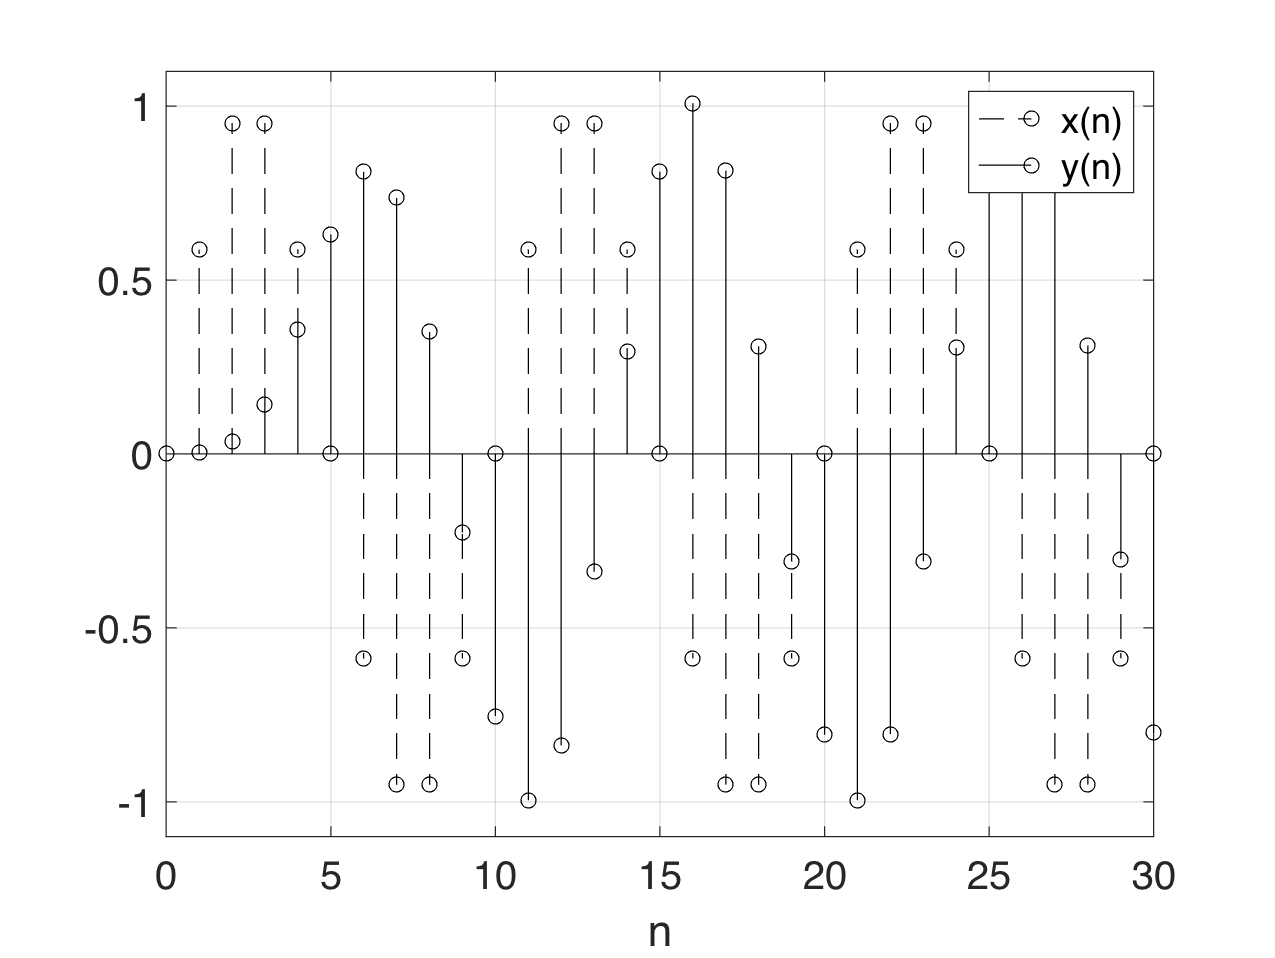

figure; hold on, box on, grid on;
stem(n,x,'k--');
stem(n,y,'k-');
set(gca,'FontSize',16,'XLim',[0 30],'YLim',[-1.1 1.1]);
xlabel('n');
legend('x(n)','y(n)');